# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'UK_ThawingDepth_daily/';

%What is the original data?
originaldata = {'UK_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/git_Research/Permafrost_ERRA/Permafrost_ERRA/figures/';

%Where is your data?
workdir = '~/Documents/git_Research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_ThawingDepth_daily';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Get the Temperatures for the range

opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["shortt", "shortt_1", "short_t_cont_num", "years", "months", "RH", "airtemp", "dewpoint", "snowdepth", "groundwater", "P", "Q","ThawDepth"];
opts.VariableTypes = ["datetime", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double","double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "shortt", "InputFormat", "yyyy-MM-dd HH:mm");
opts = setvaropts(opts, "shortt_1", "InputFormat", "yyyy-MM-dd HH:mm");

% Import the data
UKsynthesizeddata = readtable("/Users/cculha/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_ThawingDepth_daily/UK_synthesized_data.txt", opts);


ThawDepth = table2array(UKsynthesizeddata(:,"ThawDepth"));
Q = table2array(UKsynthesizeddata(:,"Q"));
P = table2array(UKsynthesizeddata(:,"P"));
Temp = table2array(UKsynthesizeddata(:,"airtemp"));

%% Clear temporary variables
clear opts


%Lets look at how many data points in each bracket
TDbraket = {'TD20_T04','TD20_T4p','TD40_T04','TD40_T4p','TD60_T04','TD60_T4p'};


NO_TD20_T04 = sum(ThawDepth<20 & Q > 0 & P > 0 & Temp>0 &Temp<4);
NO_TD20_T4p = sum(ThawDepth<20 & Q > 0 & P > 0 & Temp>=4);
NO_TD40_T04 = sum(ThawDepth>=20 & ThawDepth<40 & Q > 0 & P > 0 & Temp>0 &Temp<4);
NO_TD40_T4p = sum(ThawDepth>=20 & ThawDepth<40 & Q > 0 & P > 0 & Temp>=4);
NO_TD60_T04 = sum(ThawDepth>=40 & Q > 0 & P > 0 & Temp>0 &Temp<4);
NO_TD60_T4p = sum(ThawDepth>=40 & Q > 0 & P > 0 & Temp>=4);


Lets plot the results

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;



% %set figure page
% f1 = figure;
% set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f1,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% 
% TDbraket = {'TD10_T04','TD10_T4p','TD60_T04','TD60_T4p'};
% maxRRD = zeros(size(TDbraket));
% maxRRDlgt = zeros(size(TDbraket));
% % RRD = nan(numel(tempbraket),2000);
% % se  = nan(numel(tempbraket),2000);
% % lagt = nan(numel(tempbraket),2000);
% 
% for jj = 1:2 
% str = {'1hr_simple_',TDbraket{jj},'_RRD.txt'};
% filename=char(strcat(str(1),str(2),str(3)));
% [maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_TempBrackets(filename,workdir,workdirfig,printfig);
% end
% 
% 
% 
% 
% 
% set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});
% 
% %set axis
% xlabel('lag time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% ylabel('RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
%      
% legend("Thaw Depth $\textless 10$cm, Temperature $0-4^{\circ}$","Thaw Depth $\textless 10$cm, Temperature $\geq 4^{\circ}$",FS{[1,3]},TX{[1,2]});
% msg = sprintf('Number of valid input values \n are %d and %d respectively', NO_TD10_T04, NO_TD10_T4p);
% dim = [.55 .025 .2 .2];
% annotation('textbox', dim, 'String', msg, 'FitBoxToText','on',FS{[1,3]},TX{[1,2]});
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'ltRRD_10cm' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f1,format,resl,rend,figname,'-loose');
% end

% %set figure page
% f1 = figure;
% set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f1,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);
% 
% TDbraket = {'TD10_T04','TD10_T4p','TD60_T04','TD60_T4p'};
% maxRRD = zeros(size(TDbraket));
% maxRRDlgt = zeros(size(TDbraket));
% % RRD = nan(numel(tempbraket),2000);
% % se  = nan(numel(tempbraket),2000);
% % lagt = nan(numel(tempbraket),2000);
% 
% for jj = 3:4 
% str = {'1hr_simple_',TDbraket{jj},'_RRD.txt'};
% filename=char(strcat(str(1),str(2),str(3)));
% [maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_TempBrackets(filename,workdir,workdirfig,printfig);
% end
% 
% 
% 
% 
% 
% set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});
% 
% %set axis
% xlabel('lag time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% ylabel('RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
%      
% legend("Thaw Depth $\geq 10$cm, Temperature $0-4^{\circ}$","Thaw Depth $\geq 10$cm, Temperature $\geq 4^{\circ}$",FS{[1,3]},TX{[1,2]});
% msg = sprintf('Number of valid input values \n are %d and %d respectively', NO_TD60_T04, NO_TD60_T4p);
% dim = [.55 .025 .2 .2];
% annotation('textbox', dim, 'String', msg, 'FitBoxToText','on',FS{[1,3]},TX{[1,2]});
% %Save figure
% if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'ltRRD_60cm' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f1,format,resl,rend,figname,'-loose');
% end

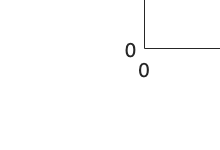

%set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


maxRRD = zeros(size(TDbraket));
maxRRDlgt = zeros(size(TDbraket));
% RRD = nan(numel(tempbraket),2000);
% se  = nan(numel(tempbraket),2000);
% lagt = nan(numel(tempbraket),2000);

for jj = [1 3 5] 
str = {'1hr_simple_',TDbraket{jj},'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_TempBrackets(filename,workdir,workdirfig,printfig);
end

Error using matlab.io.ImportOptions/readtable
Unable to find or open '1hr_simple_TD20_T04_RRD.txt'. Check the path and filename or file permissions.

Error in figtRRD_plot_TempBrackets (line 29)
dat = readtable(filename, opts);






set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('lag time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
     
legend("Thaw Depth $\textless 20$cm, Temperature $0-4^{\circ}$","Thaw Depth $\geq 20$ and $\textless 40$cm, Temperature $0-4^{\circ}$","Thaw Depth $\geq 40$cm, Temperature $0-4^{\circ}$",FS{[1,3]},TX{[1,2]});
msg = sprintf('Number of valid input values \n are %d, %d, and %d respectively', NO_TD20_T04, NO_TD40_T04, NO_TD60_T04);
dim = [.55 .025 .2 .2];
annotation('textbox', dim, 'String', msg, 'FitBoxToText','on',FS{[1,3]},TX{[1,2]});
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD_T04' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

%set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

% TDbraket = {'TD20_T04','TD10_T4p','TD60_T04','TD60_T4p'};
maxRRD = zeros(size(TDbraket));
maxRRDlgt = zeros(size(TDbraket));
% RRD = nan(numel(tempbraket),2000);
% se  = nan(numel(tempbraket),2000);
% lagt = nan(numel(tempbraket),2000);

for jj = [2 4 6] 
str = {'1hr_simple_',TDbraket{jj},'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_TempBrackets(filename,workdir,workdirfig,printfig);
end





set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('lag time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
     
legend("Thaw Depth $\textless 20$cm, Temperature $\geq 4^{\circ}$","Thaw Depth $\geq 20$ and $\textless 40$cm, Temperature $\geq 4^{\circ}$","Thaw Depth $\geq 40$cm, Temperature $\geq 4^{\circ}$",FS{[1,3]},TX{[1,2]});
msg = sprintf('Number of valid input values \n are %d, %d and %d respectively', NO_TD20_T4p, NO_TD40_T4p, NO_TD60_T4p);
dim = [.55 .025 .2 .2];
annotation('textbox', dim, 'String', msg, 'FitBoxToText','on',FS{[1,3]},TX{[1,2]});
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD_T4p' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end